# Salen-key filter verification

## References

- wiki, [Sallen–Key topology](https://en.wikipedia.org/wiki/Sallen%E2%80%93Key_topology)

- Okawa Denshi, [Sallen-Key Low-pass Filter Design Tool](http://sim.okawa-denshi.jp/en/OPseikiLowkeisan.htm)

- Okawa Denshi, [3rd order Sallen-Key Low-pass Filter Design Tool](http://sim.okawa-denshi.jp/en/Sallenkey3Lowkeisan.htm)

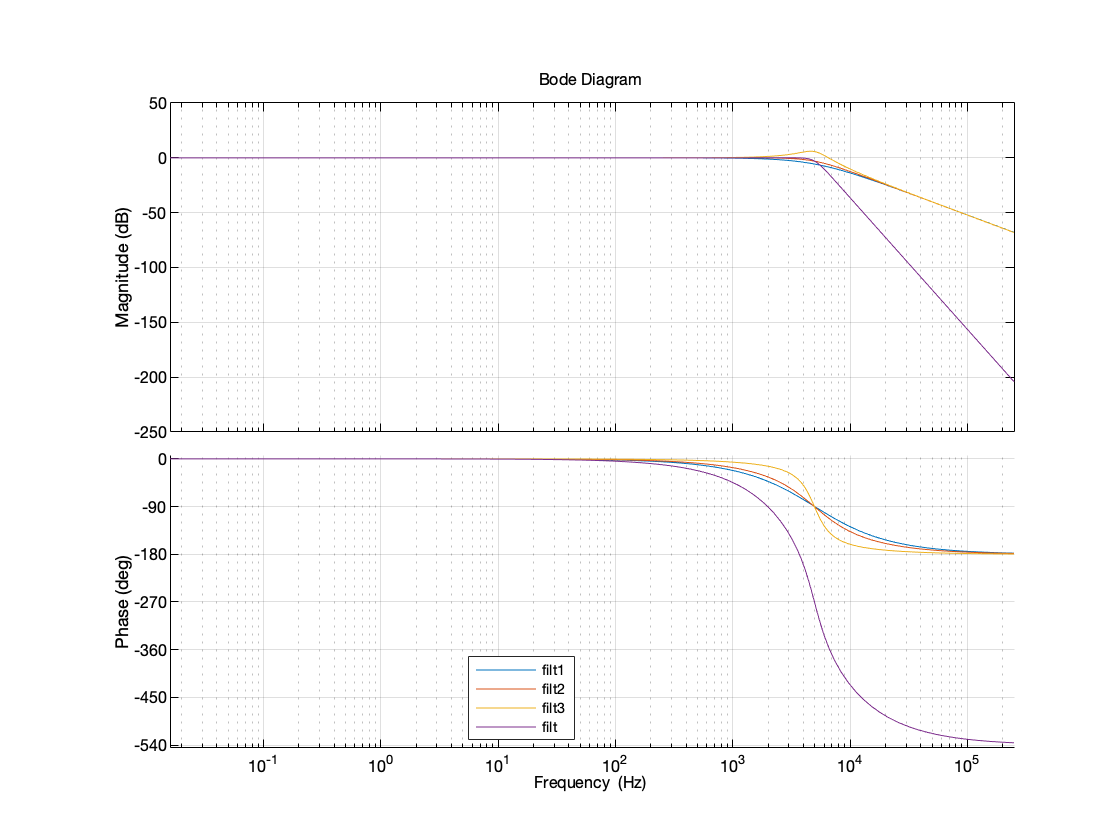

%% The first stage parameters
R1 = 111e3;
R2 = 19.4e3;
C1 = 1e-9;
C2 = 470e-12;

%% The second stage parameters
R3 = 108.25e3;
R4 = 28.81e3;
C3 = 1e-9;
C4 = 330e-12;

%% The third stage parameters
R5 = 41.45e3;
R6 = 123.7e3;
C5 = 2e-9;
C6 = 100e-12;

%% Calculation and drawing diagram
[a11, b11, b12, b13] = para_sk(R1, R2, C1, C2);
[a21, b21, b22, b23] = para_sk(R3, R4, C3, C4);
[a31, b31, b32, b33] = para_sk(R5, R6, C5, C6);

filt1 = tf(a11, [b11 b12 b13]);
filt2 = tf(a21, [b21 b22 b23]);
filt3 = tf(a31, [b31 b32 b33]);
filt = filt1*filt2*filt3;

P = bodeoptions;
P.PhaseUnits = 'deg';
P.FreqUnits = 'Hz';

figure;
bodeplot(filt1,{0.1,2*pi*5*50e3}, P);
hold on; grid on; box off;
bodeplot(filt2,{0.1,2*pi*5*50e3});
bodeplot(filt3,{0.1,2*pi*5*50e3});
bodeplot(filt,{0.1,2*pi*5*50e3});
legend('filt1', 'filt2', 'filt3', 'filt', 'Location', 'best');

## 10Hz 3rd order sallen-key filter

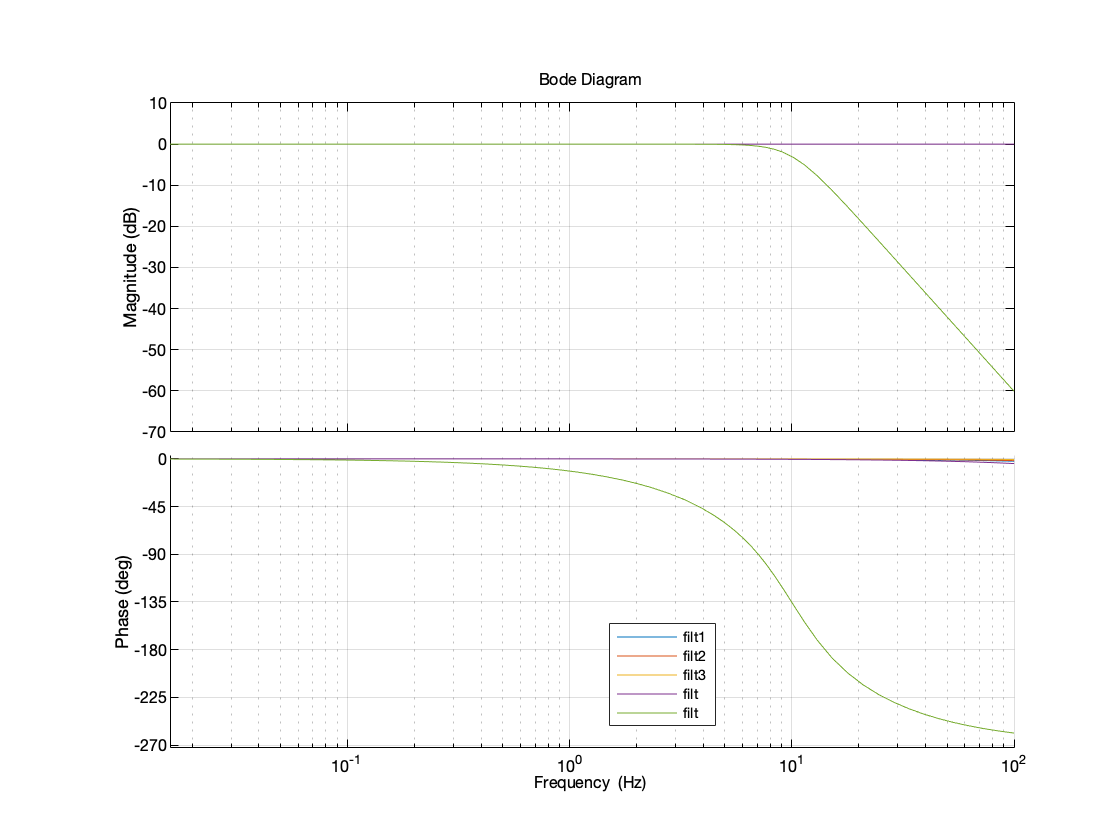

%% The first stage parameters

R1 = 11e3;
C1 = 1500e-9;

%% The second stage parameters
R2 = 110e3;
R3 = 33e3;
C2 = 680e-9;
C3 = 100e-9;

[a1, b1, b2, b3, b4] = para_sk_3rd(R1, R2, R3, C1, C2, C3);
filt = tf(a1, [b1 b2 b3 b4]);
bodeplot(filt,{0.1,2*pi*10*10}, P);
hold on; grid on; box off;

## 1.5Hz 3rd order sallen-key filter

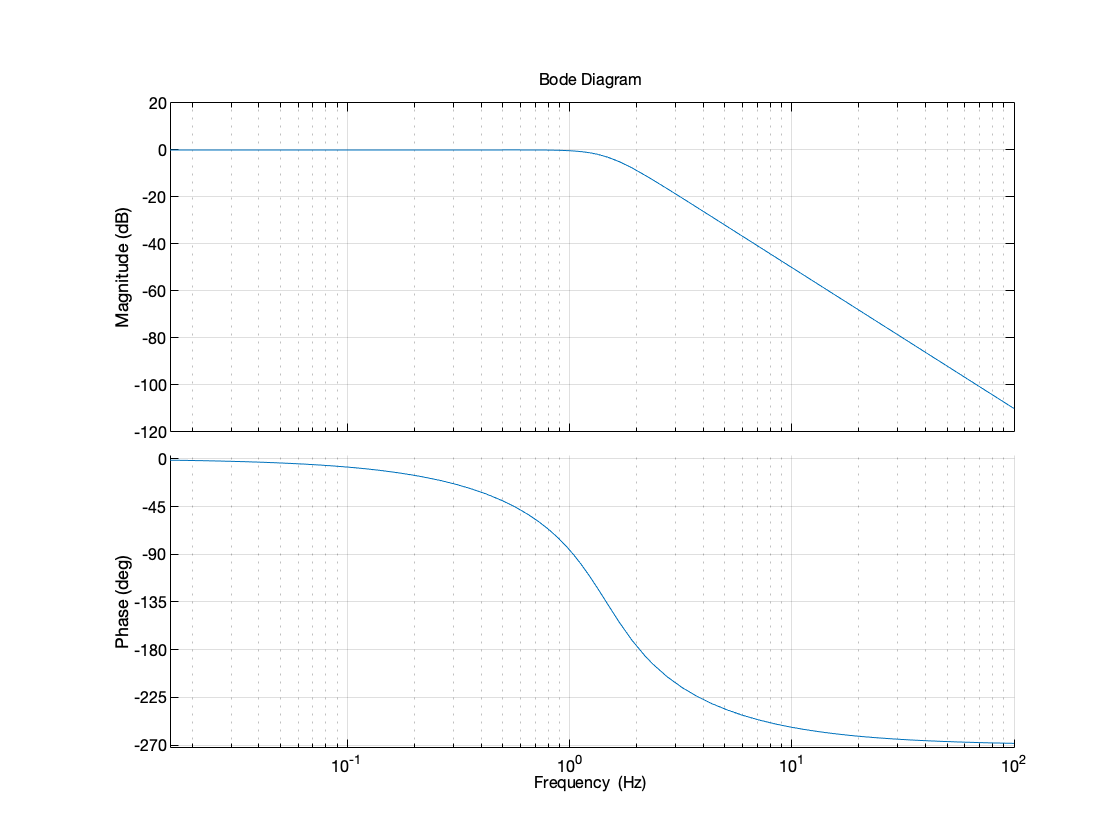


%% The first stage parameters

R1 = 11e3;
C1 = 10e-6;

%% The second stage parameters
R2 = 110e3;
R3 = 33e3;
C2 = 4700e-9;
C3 = 680e-9;

[a1, b1, b2, b3, b4] = para_sk_3rd(R1, R2, R3, C1, C2, C3);
filt = tf(a1, [b1 b2 b3 b4]);

figure;
bodeplot(filt,{0.1,2*pi*10*10}, P);
hold on; grid on; box off;

## 1Hz 3rd order sallen-key filter

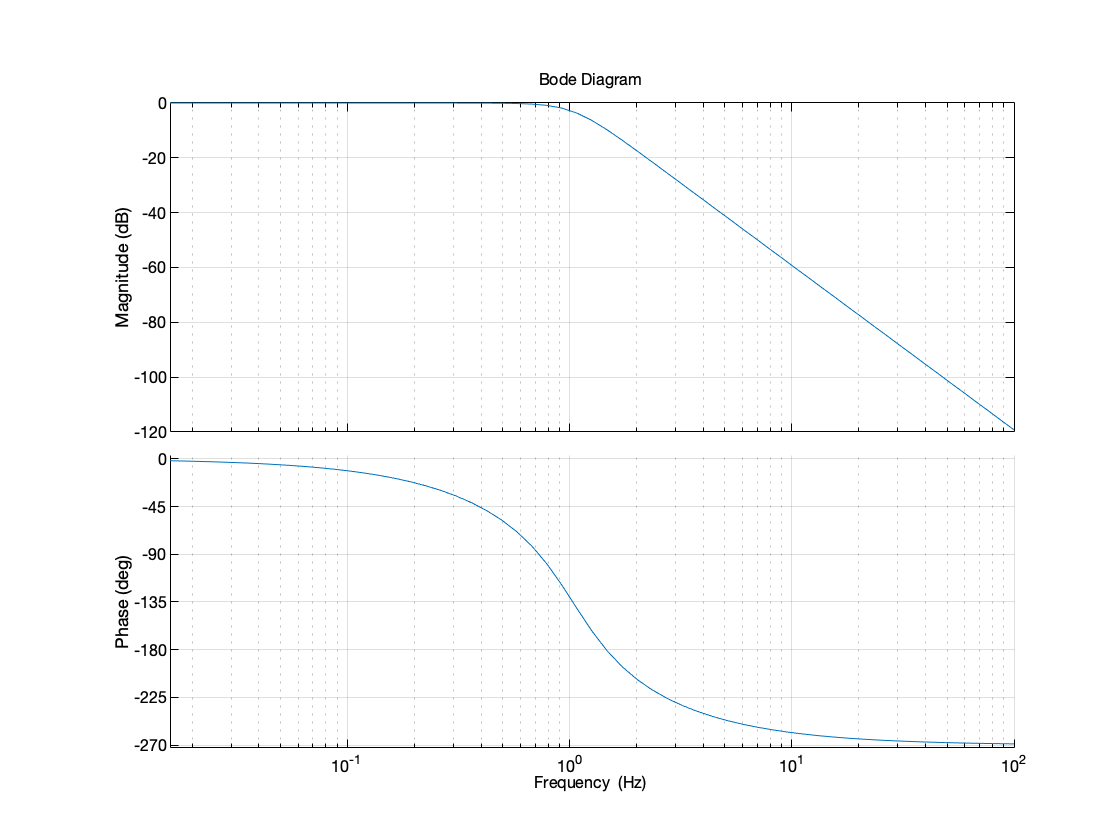

% The first stage parameters
R1 = 110e3;
C1 = 1.5e-6;

% The second stage parameters
R2 = 620e3;
R3 = 240e3;
C2 = 1000e-9;
C3 = 150e-9;

[a1, b1, b2, b3, b4] = para_sk_3rd(R1, R2, R3, C1, C2, C3);
filt = tf(a1, [b1 b2 b3 b4]);

figure;
bodeplot(filt,{0.1,2*pi*10*10}, P);
hold on; grid on; box off;